# **Convergence and Divergence of Taylor Series**

## **1. **Taylor's Theorem and Taylor Series

Taylor's theorem says that if $f(x)$ is $C^\infty$ near $x=a$ then for any $N=1,2,3,\ldots$


$$f(x)
=
\sum_{n=0}^{N-1}
\frac{f^{(n)}(a)}{n!}
(x-a)^n
+
R_N(x),$$



$$R_N(x)
=
\frac{f^{(N)}\bigl(\theta{x}+(1-\theta)a\bigr)}{n!}
(x-a)^N
=
\frac{(x-a)^N}{(N-1)!}
\int_0^1
f^{(N)}\bigl(tx+(1-t)a\bigr)
dt,$$


where $\theta
=
\theta(x,a,N)
\in
(0,1)$ is a constant depending on $x$, $a$, and $N$. 

For some smooth function $f$ and for some $x$, we have 


$$f(x)
-
\sum_{n=0}^{N-1}
\frac{f^{(n)}(a)}{n!}
(x-a)^n
=
R_N(x)
\rightarrow 
0
\quad
\text{as}
\quad
N \rightarrow \infty.$$


In this case it is well-known that there exists $\rho\in(0,\infty]$ such that 


$$f(x)
=
\sum_{n=0}^\infty
\frac{f^{(n)}(a)}{n!}
(x-a)^n, 
\quad
x \in (a-\rho,a+\rho).$$


The right hand side of the above is said to be the Taylor series 

or the Taylor expansion of $f(x)$ at center $x=a$ with convergence radius $\rho$.

## 2. Examples of Taylor Expansions


$$(1+x)^\alpha
=
\sum_{n=0}^\infty
\pmatrix{\alpha \cr n}
x^n,
\quad
x\in(-1,1),
\quad
\alpha\in\mathbb{C}, $$



$$\pmatrix{\alpha \cr n}
=
\frac{\alpha(\alpha-1)\cdots(\alpha-n+1)}{n!}
\quad
(n=1,2,3,\ldots),
\qquad
\pmatrix{\alpha \cr 0}
=
1,$$



$$\log(1+x)
=
\sum_{n=1}^\infty
\frac{(-1)^{n-1}x^n}{n},
\quad
x\in(-1,1],$$



$$e^x
=
\sum_{n=0}^\infty
\frac{x^n}{n!},
\quad
x\in\mathbb{R},$$



$$\cos{x}
=
\sum_{k=0}^\infty
\frac{(-1)^kx^{2k}}{(2k)!},
\quad
x\in\mathbb{R},$$



$$\sin{x}
=
\sum_{k=0}^\infty
\frac{(-1)^kx^{2k+1}}{(2k+1)!},
\quad
x\in\mathbb{R},$$


## 3. Observation #1

For any $\varepsilon\in(0,1)$


$$\max_{x\in[-1+\varepsilon,1]}
\left|
(1+x)^{-1/2}
-
\sum_{n=0}^N
\frac{(-1)^n(2n)!x^n}{2^{2n}(n!)^2}
\right|
\rightarrow
0
\quad
(N\rightarrow\infty).$$


L1 = 35;
x1 = linspace(-1,1.5,101);
y1 = zeros(L1+1,length(x1));
y1(1,:) = 1;
for n=2:L1+1
    y1(n,:)=y1(n-1,:)+power(-1,n-1)*factorial(2*(n-1))*power(x1,n-1)/power(2,2*(n-1))/factorial(n-1)/factorial(n-1);
end

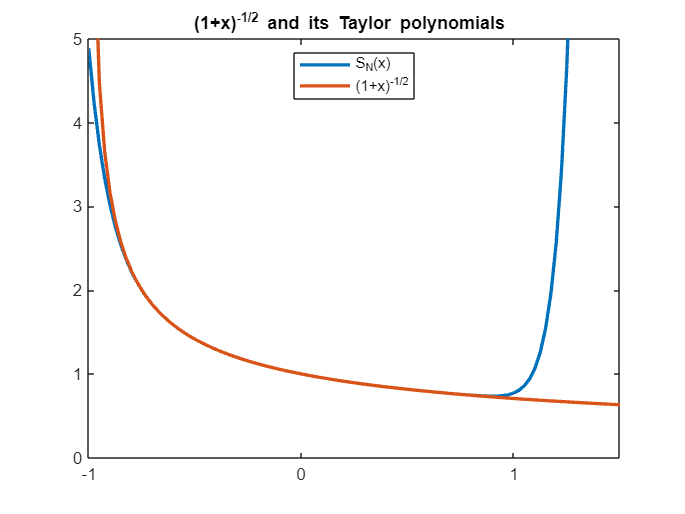

N =18;
plot(x1,y1(N+1,:),x1,power(1+x1,-1/2),'LineWidth',2)
    ylim([0 5])
    title('(1+x)^{-1/2} and its Taylor polynomials ')
    xticks([-1 0 1])
    xticklabels({'-1','0','1'})
    yticks([0 1 2 3 4 5])
    yticklabels({'0','1','2','3','4','5'})
    legend('S_N(x)','(1+x)^{-1/2}','Location','north')

## 4. Observation #2

For any $\varepsilon\in(0,1)$


$$\max_{x\in[-1+\varepsilon,1]}
\left|
\log(1+x)
-
\sum_{n=1}^N
\frac{(-1)^{n-1}x^n}{n}
\right|
\rightarrow
0
\quad
(N\rightarrow\infty).$$


L2 = 30;
x2 = linspace(-1,1.5,101);
y2 = zeros(L2,length(x2));
y2(1,:) = x2;
for n=2:L2
    y2(n,:)=y2(n-1,:)+power(-1,n-1)*power(x2,n)/n;
end

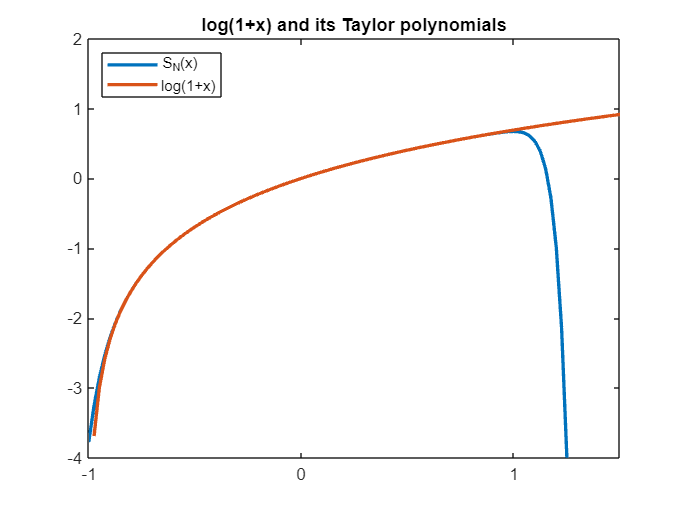

N =24;
plot(x2,y2(N,:),x2,log(1+x2),'LineWidth',2)
    ylim([-4 2])
    title('log(1+x) and its Taylor polynomials')
    xticks([-1 0 1])
    xticklabels({'-1','0','1'})
    yticks([-4 -3 -2 -1 0 1 2])
    yticklabels({'-4','-3','-2','-1','0','1','2'})
    legend('S_N(x)','log(1+x)','Location','northwest')

## 5. Observation #3

For any $R>0$


$$\max_{x\in[-R,R]}
\left|
\sin{x}
-
\sum_{k=0}^K
\frac{(-1)^kx^{2k+1}}{(2k+1)!}
\right|
\rightarrow
0
\quad
(K\rightarrow\infty).$$


L3 = 12;
x3 = linspace(-3*pi,3*pi,101);
y3 = zeros(L3+1,length(x3));
y3(1,:) = x3;
for k=2:L3+1
    y3(k,:)=y3(k-1,:)+power(-1,k-1)*power(x3,2*k-1)/factorial(2*k-1);    
end

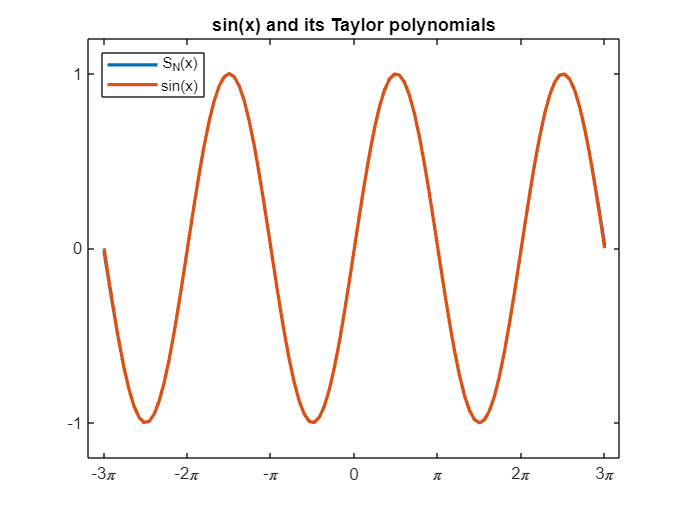

K =12 ;
plot(x3,y3(K+1,:),x3,sin(x3),'LineWidth',2)
    ylim([-1.2 1.2])
    title('sin(x) and its Taylor polynomials')
    xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
    xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
    yticks([-1 0 1])
    yticklabels({'-1','0','1'})
    legend('S_N(x)','sin(x)','Location','northwest')